## Maximizing ODMR contrast

First optimize for the read out time. Take \beta = 0.3

% ODMR_contrast = cycle_1_PL_signal() - cycle_2_PL_signal(T_pi);
% cycle_2_PL_signal(0.1, 0.3, 0.3)
% cycle_1_PL_signal(0.3, 0.9)
% calc_ODMR_contrast(0.3, 0.3)

beta = 0.3;

ans = 0.0103

T_rd_arr = 1e-3 : 1e-1 : 10

T_rd_arr =     0.0010    0.1010    0.2010    0.3010    0.4010    0.5010    0.6010    0.7010    0.8010    0.9010    1.0010    1.1010    1.2010    1.3010    1.4010    1.5010    1.6010    1.7010    1.8010    1.9010    2.0010    2.1010    2.2010    2.3010    2.4010    2.5010    2.6010    2.7010    2.8010    2.9010    3.0010    3.1010    3.2010    3.3010    3.4010    3.5010    3.6010    3.7010    3.8010    3.9010    4.0010    4.1010    4.2010    4.3010    4.4010    4.5010    4.6010    4.7010    4.8010    4.9010


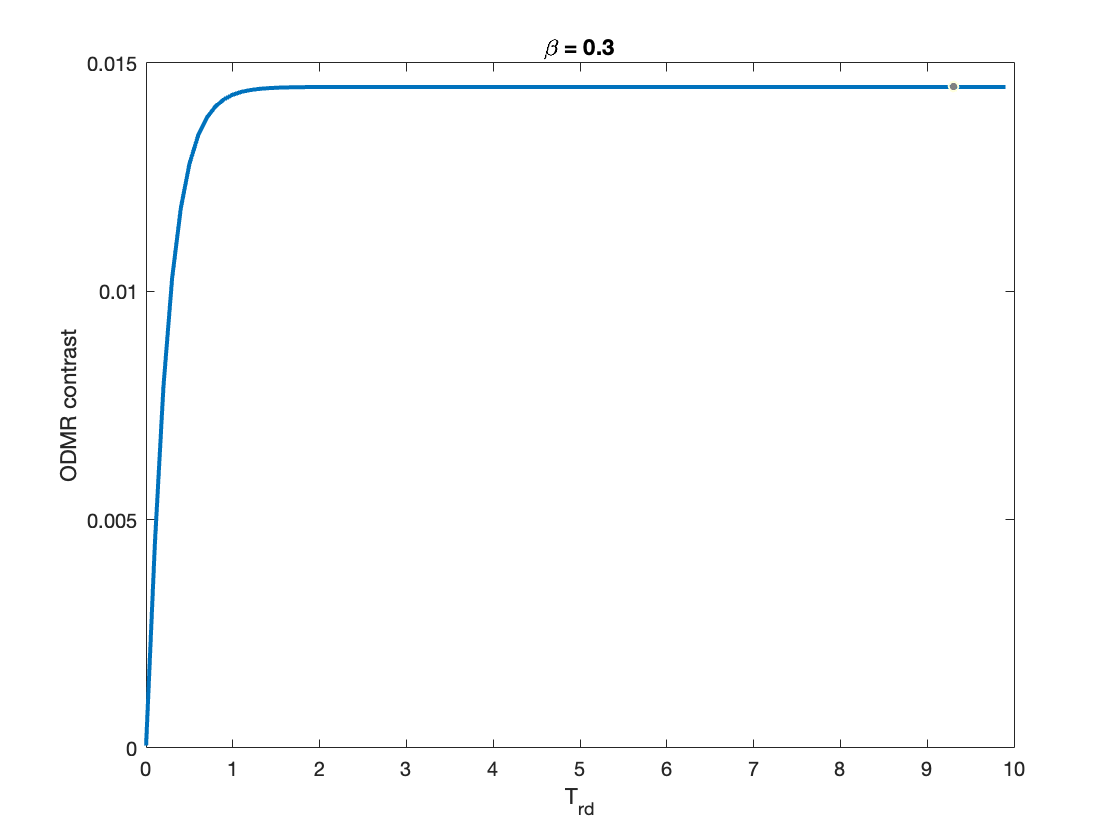

length = size(T_rd_arr);
ODMR_contrast_arr = zeros(length(2), 1);
for i = 1 : length(2)
    ODMR_contrast_arr(i, 1) = calc_ODMR_contrast(beta, T_rd_arr(i));
end

plot(T_rd_arr, ODMR_contrast_arr, 'LineWidth', 2)
xlabel('T_{rd}');
ylabel('ODMR contrast');
title('\beta = 0.3');

function contrast = calc_ODMR_contrast(beta, T_rd)
    T_pi = 0.1;
    contrast = cycle_1_PL_signal(beta, T_rd) - cycle_2_PL_signal(T_pi, beta, T_rd);
end

function signal = cycle_2_PL_signal(T_swp, beta_in, T_rd)
    %----------------------------------------------------------------------
    % Parameters and equations
    T_pi = 0.1;      %100 ns
    K0 = zeros(7,7);

    beta = 0;
    k0_r = 63;
    k0_47 = 13;
    k0_57 = 80;
    k0_71 = 3.5;
    k0_72 = 2.2;
    K0(1,4) = beta*k0_r;
    K0(2,5) = beta*k0_r;
    K0(3,6) = beta*k0_r;
    K0(4,1) = k0_r;
    K0(5,2) = k0_r;
    K0(6,3) = k0_r;
    K0(4,7) = k0_47;
    K0(5,7) = k0_57;
    K0(6,7) = k0_57;
    K0(7,1) = k0_71;
    K0(7,2) = k0_72;
    K0(7,3) = k0_72;

    K0_OFF = K0;   %K matrix when laser is off (/beta = 0)

    ode1_OFF = @(t, y) K0_OFF(1,1)*y(1) - K0_OFF(1,1)*y(1)...
                 + K0_OFF(2,1)*y(2) - K0_OFF(1,2)*y(1)...
                 + K0_OFF(3,1)*y(3) - K0_OFF(1,3)*y(1)...
                 + K0_OFF(4,1)*y(4) - K0_OFF(1,4)*y(1)...
                 + K0_OFF(5,1)*y(5) - K0_OFF(1,5)*y(1)...
                 + K0_OFF(6,1)*y(6) - K0_OFF(1,6)*y(1)...
                 + K0_OFF(7,1)*y(7) - K0_OFF(1,7)*y(1);

    ode2_OFF = @(t, y) K0_OFF(1,2)*y(1) - K0_OFF(2,1)*y(2)...
                 + K0_OFF(2,2)*y(2) - K0_OFF(2,2)*y(2)...
                 + K0_OFF(3,2)*y(3) - K0_OFF(2,3)*y(2)...
                 + K0_OFF(4,2)*y(4) - K0_OFF(2,4)*y(2)...
                 + K0_OFF(5,2)*y(5) - K0_OFF(2,5)*y(2)...
                 + K0_OFF(6,2)*y(6) - K0_OFF(2,6)*y(2)...
                 + K0_OFF(7,2)*y(7) - K0_OFF(2,7)*y(2);

    ode3_OFF = @(t, y) K0_OFF(1,3)*y(1) - K0_OFF(3,1)*y(3)...
                 + K0_OFF(2,3)*y(2) - K0_OFF(3,2)*y(3)...
                 + K0_OFF(3,3)*y(3) - K0_OFF(3,3)*y(3)...
                 + K0_OFF(4,3)*y(4) - K0_OFF(3,4)*y(3)...
                 + K0_OFF(5,3)*y(5) - K0_OFF(3,5)*y(3)...
                 + K0_OFF(6,3)*y(6) - K0_OFF(3,6)*y(3)...
                 + K0_OFF(7,3)*y(7) - K0_OFF(3,7)*y(3);

    ode4_OFF = @(t, y) K0_OFF(1,4)*y(1) - K0_OFF(4,1)*y(4)...
                 + K0_OFF(2,4)*y(2) - K0_OFF(4,2)*y(4)...
                 + K0_OFF(3,4)*y(3) - K0_OFF(4,3)*y(4)...
                 + K0_OFF(4,4)*y(4) - K0_OFF(4,4)*y(4)...
                 + K0_OFF(5,4)*y(5) - K0_OFF(4,5)*y(4)...
                 + K0_OFF(6,4)*y(6) - K0_OFF(4,6)*y(4)...
                 + K0_OFF(7,4)*y(7) - K0_OFF(4,7)*y(4);

    ode5_OFF = @(t, y) K0_OFF(1,5)*y(1) - K0_OFF(5,1)*y(5)...
                 + K0_OFF(2,5)*y(2) - K0_OFF(5,2)*y(5)...
                 + K0_OFF(3,5)*y(3) - K0_OFF(5,3)*y(5)...
                 + K0_OFF(4,5)*y(4) - K0_OFF(5,4)*y(5)...
                 + K0_OFF(5,5)*y(5) - K0_OFF(5,5)*y(5)...
                 + K0_OFF(6,5)*y(6) - K0_OFF(5,6)*y(5)...
                 + K0_OFF(7,5)*y(7) - K0_OFF(5,7)*y(5);

    ode6_OFF = @(t, y) K0_OFF(1,6)*y(1) - K0_OFF(6,1)*y(6)...
                 + K0_OFF(2,6)*y(2) - K0_OFF(6,2)*y(6)...
                 + K0_OFF(3,6)*y(3) - K0_OFF(6,3)*y(6)...
                 + K0_OFF(4,6)*y(4) - K0_OFF(6,4)*y(6)...
                 + K0_OFF(5,6)*y(5) - K0_OFF(6,5)*y(6)...
                 + K0_OFF(6,6)*y(6) - K0_OFF(6,6)*y(6)...
                 + K0_OFF(7,6)*y(7) - K0_OFF(6,7)*y(6);

    ode7_OFF = @(t, y) K0_OFF(1,7)*y(1) - K0_OFF(7,1)*y(7)...
                 + K0_OFF(2,7)*y(2) - K0_OFF(7,2)*y(7)...
                 + K0_OFF(3,7)*y(3) - K0_OFF(7,3)*y(7)...
                 + K0_OFF(4,7)*y(4) - K0_OFF(7,4)*y(7)...
                 + K0_OFF(5,7)*y(5) - K0_OFF(7,5)*y(7)...
                 + K0_OFF(6,7)*y(6) - K0_OFF(7,6)*y(7)...
                 + K0_OFF(7,7)*y(7) - K0_OFF(7,7)*y(7);

    odes_OFF = @(t, n) [ode1_OFF(t, n); ode2_OFF(t, n); ode3_OFF(t, n); 
        ode4_OFF(t, n); ode5_OFF(t, n); ode6_OFF(t, n); ode7_OFF(t, n)];
    %----------------------------------------------------------------------

    K0 = zeros(7,7);

    beta = beta_in;
    k0_r = 63;
    k0_47 = 13;
    k0_57 = 80;
    k0_71 = 3.5;
    k0_72 = 2.2;
    K0(1,4) = beta*k0_r;
    K0(2,5) = beta*k0_r;
    K0(3,6) = beta*k0_r;
    K0(4,1) = k0_r;
    K0(5,2) = k0_r;
    K0(6,3) = k0_r;
    K0(4,7) = k0_47;
    K0(5,7) = k0_57;
    K0(6,7) = k0_57;
    K0(7,1) = k0_71;
    K0(7,2) = k0_72;
    K0(7,3) = k0_72;

    K0_ON = K0;       %K matrix when laser is on (/beta = 0.3)

    ode1_ON = @(t, y) K0_ON(1,1)*y(1) - K0_ON(1,1)*y(1)...
                 + K0_ON(2,1)*y(2) - K0_ON(1,2)*y(1)...
                 + K0_ON(3,1)*y(3) - K0_ON(1,3)*y(1)...
                 + K0_ON(4,1)*y(4) - K0_ON(1,4)*y(1)...
                 + K0_ON(5,1)*y(5) - K0_ON(1,5)*y(1)...
                 + K0_ON(6,1)*y(6) - K0_ON(1,6)*y(1)...
                 + K0_ON(7,1)*y(7) - K0_ON(1,7)*y(1);

    ode2_ON = @(t, y) K0_ON(1,2)*y(1) - K0_ON(2,1)*y(2)...
                 + K0_ON(2,2)*y(2) - K0_ON(2,2)*y(2)...
                 + K0_ON(3,2)*y(3) - K0_ON(2,3)*y(2)...
                 + K0_ON(4,2)*y(4) - K0_ON(2,4)*y(2)...
                 + K0_ON(5,2)*y(5) - K0_ON(2,5)*y(2)...
                 + K0_ON(6,2)*y(6) - K0_ON(2,6)*y(2)...
                 + K0_ON(7,2)*y(7) - K0_ON(2,7)*y(2);

    ode3_ON = @(t, y) K0_ON(1,3)*y(1) - K0_ON(3,1)*y(3)...
                 + K0_ON(2,3)*y(2) - K0_ON(3,2)*y(3)...
                 + K0_ON(3,3)*y(3) - K0_ON(3,3)*y(3)...
                 + K0_ON(4,3)*y(4) - K0_ON(3,4)*y(3)...
                 + K0_ON(5,3)*y(5) - K0_ON(3,5)*y(3)...
                 + K0_ON(6,3)*y(6) - K0_ON(3,6)*y(3)...
                 + K0_ON(7,3)*y(7) - K0_ON(3,7)*y(3);

    ode4_ON = @(t, y) K0_ON(1,4)*y(1) - K0_ON(4,1)*y(4)...
                 + K0_ON(2,4)*y(2) - K0_ON(4,2)*y(4)...
                 + K0_ON(3,4)*y(3) - K0_ON(4,3)*y(4)...
                 + K0_ON(4,4)*y(4) - K0_ON(4,4)*y(4)...
                 + K0_ON(5,4)*y(5) - K0_ON(4,5)*y(4)...
                 + K0_ON(6,4)*y(6) - K0_ON(4,6)*y(4)...
                 + K0_ON(7,4)*y(7) - K0_ON(4,7)*y(4);

    ode5_ON = @(t, y) K0_ON(1,5)*y(1) - K0_ON(5,1)*y(5)...
                 + K0_ON(2,5)*y(2) - K0_ON(5,2)*y(5)...
                 + K0_ON(3,5)*y(3) - K0_ON(5,3)*y(5)...
                 + K0_ON(4,5)*y(4) - K0_ON(5,4)*y(5)...
                 + K0_ON(5,5)*y(5) - K0_ON(5,5)*y(5)...
                 + K0_ON(6,5)*y(6) - K0_ON(5,6)*y(5)...
                 + K0_ON(7,5)*y(7) - K0_ON(5,7)*y(5);

    ode6_ON = @(t, y) K0_ON(1,6)*y(1) - K0_ON(6,1)*y(6)...
                 + K0_ON(2,6)*y(2) - K0_ON(6,2)*y(6)...
                 + K0_ON(3,6)*y(3) - K0_ON(6,3)*y(6)...
                 + K0_ON(4,6)*y(4) - K0_ON(6,4)*y(6)...
                 + K0_ON(5,6)*y(5) - K0_ON(6,5)*y(6)...
                 + K0_ON(6,6)*y(6) - K0_ON(6,6)*y(6)...
                 + K0_ON(7,6)*y(7) - K0_ON(6,7)*y(6);

    ode7_ON = @(t, y) K0_ON(1,7)*y(1) - K0_ON(7,1)*y(7)...
                 + K0_ON(2,7)*y(2) - K0_ON(7,2)*y(7)...
                 + K0_ON(3,7)*y(3) - K0_ON(7,3)*y(7)...
                 + K0_ON(4,7)*y(4) - K0_ON(7,4)*y(7)...
                 + K0_ON(5,7)*y(5) - K0_ON(7,5)*y(7)...
                 + K0_ON(6,7)*y(6) - K0_ON(7,6)*y(7)...
                 + K0_ON(7,7)*y(7) - K0_ON(7,7)*y(7);

    odes_ON = @(t, n) [ode1_ON(t, n); ode2_ON(t, n); ode3_ON(t, n); 
        ode4_ON(t, n); ode5_ON(t, n); ode6_ON(t, n); ode7_ON(t, n)];
    %----------------------------------------------------------------------
    % Simulation
    % Laser 1
    init_laser_1 = [1/3; 1/3; 1/3; 0; 0; 0; 0];
    [t, n_res_laser_1] = ode45(odes_ON, [0 : 1e-3 : 5180e-3], init_laser_1);
    
    % Delay 1
    init_delay_1 = get_init(n_res_laser_1);
    [t, n_res_delay_1] = ode45(odes_OFF, [5.18 : 1e-3 : 11.192], init_delay_1);
    n_res_delay_1(1,:) = [];
    
    % MW
    init_mw = get_init(n_res_delay_1);
    
    t3 = 0 : 1e-3 : T_swp;
    length = size(t3);
    n_1_0 = init_mw(1,1);
    n_2_0 = init_mw(2,1);
    n_1_tp = (n_1_0 - n_2_0)/2 * cos(pi * t3 / T_pi) + (n_1_0 + n_2_0)/2;
    n_2_tp = (n_1_0 + n_2_0) - n_1_tp;

    n_res_mw = zeros(length(2), 7);
    n_res_mw(:, 1) = n_1_tp;
    n_res_mw(:, 2) = n_2_tp;
    for i = 3:7
        n_res_mw(:, i) = init_mw(i, 1) .* ones(length(2), 1);
    end
    n_res_mw(1, :) = [];
    
    % Delay 2
    init_delay_2 = get_init(n_res_mw);
    [t, n_res_delay_2] = ode45(odes_OFF, [T_swp + 11.192 : 1e-3 : T_swp + 12.204], init_delay_2);
    n_res_delay_2(1, :) = [];
    
    % Laser 2
    init_laser_2 = get_init(n_res_delay_2);
    [t, n_res_laser_2] = ode45(odes_ON, [T_swp + 12.204 : 1e-3 : T_swp + 12.204 + T_rd], init_laser_2);
    n_res_laser_2(1, :) = [];
    
    % Delay 3
    init_delay_3 = get_init(n_res_laser_2);
    [t, n_res_delay_3] = ode45(odes_OFF, [T_swp + 12.204 + T_rd : 1e-3 : T_swp + 12.804 + T_rd ], init_delay_3);
    n_res_delay_2(1, :) = [];
    
    % Calculation of the PL signal
    n_res = [n_res_laser_1; n_res_delay_1; n_res_mw; n_res_delay_2; n_res_laser_2; n_res_delay_3];
    n_res_4 = n_res(:, 4);
    n_res_5 = n_res(:, 5);
    n_res_6 = n_res(:, 6);
    I_PL = n_res_4 + n_res_5 + n_res_6;
    
%     plot(t, I_PL, "LineWidth", 1.5);
%     xlabel('Time (\mus)');
%     ylabel("PL");
%     legend("I_{PL} = n_4 + n_5 + n_6")
%     title("T_{swp} = 0.06 \mus")
    
    t = 12 : 1e-3 : T_swp + T_rd + 12.804;  
    signal = trapz(t, I_PL(12000 : round((T_swp + 12.804 + T_rd ) * 1000)));
%     plot(t, I_PL(12000 : (T_swp + 12.804 + T_rd ) * 1000), "LineWidth", 1);
%     xlabel('Time (\mus)');
%     ylabel("PL");
end

function signal = cycle_1_PL_signal(beta_in, T_rd)
    %----------------------------------------------------------------------
    % Parameters and equations
    T_pi = 0.1;      %100 ns
    K0 = zeros(7,7);

    beta = 0;
    
    k0_r = 63;
    k0_47 = 13;
    k0_57 = 80;
    k0_71 = 3.5;
    k0_72 = 2.2;
    K0(1,4) = beta*k0_r;
    K0(2,5) = beta*k0_r;
    K0(3,6) = beta*k0_r;
    K0(4,1) = k0_r;
    K0(5,2) = k0_r;
    K0(6,3) = k0_r;
    K0(4,7) = k0_47;
    K0(5,7) = k0_57;
    K0(6,7) = k0_57;
    K0(7,1) = k0_71;
    K0(7,2) = k0_72;
    K0(7,3) = k0_72;

    K0_OFF = K0;   %K matrix when laser is off (/beta = 0)

    ode1_OFF = @(t, y) K0_OFF(1,1)*y(1) - K0_OFF(1,1)*y(1)...
                 + K0_OFF(2,1)*y(2) - K0_OFF(1,2)*y(1)...
                 + K0_OFF(3,1)*y(3) - K0_OFF(1,3)*y(1)...
                 + K0_OFF(4,1)*y(4) - K0_OFF(1,4)*y(1)...
                 + K0_OFF(5,1)*y(5) - K0_OFF(1,5)*y(1)...
                 + K0_OFF(6,1)*y(6) - K0_OFF(1,6)*y(1)...
                 + K0_OFF(7,1)*y(7) - K0_OFF(1,7)*y(1);

    ode2_OFF = @(t, y) K0_OFF(1,2)*y(1) - K0_OFF(2,1)*y(2)...
                 + K0_OFF(2,2)*y(2) - K0_OFF(2,2)*y(2)...
                 + K0_OFF(3,2)*y(3) - K0_OFF(2,3)*y(2)...
                 + K0_OFF(4,2)*y(4) - K0_OFF(2,4)*y(2)...
                 + K0_OFF(5,2)*y(5) - K0_OFF(2,5)*y(2)...
                 + K0_OFF(6,2)*y(6) - K0_OFF(2,6)*y(2)...
                 + K0_OFF(7,2)*y(7) - K0_OFF(2,7)*y(2);

    ode3_OFF = @(t, y) K0_OFF(1,3)*y(1) - K0_OFF(3,1)*y(3)...
                 + K0_OFF(2,3)*y(2) - K0_OFF(3,2)*y(3)...
                 + K0_OFF(3,3)*y(3) - K0_OFF(3,3)*y(3)...
                 + K0_OFF(4,3)*y(4) - K0_OFF(3,4)*y(3)...
                 + K0_OFF(5,3)*y(5) - K0_OFF(3,5)*y(3)...
                 + K0_OFF(6,3)*y(6) - K0_OFF(3,6)*y(3)...
                 + K0_OFF(7,3)*y(7) - K0_OFF(3,7)*y(3);

    ode4_OFF = @(t, y) K0_OFF(1,4)*y(1) - K0_OFF(4,1)*y(4)...
                 + K0_OFF(2,4)*y(2) - K0_OFF(4,2)*y(4)...
                 + K0_OFF(3,4)*y(3) - K0_OFF(4,3)*y(4)...
                 + K0_OFF(4,4)*y(4) - K0_OFF(4,4)*y(4)...
                 + K0_OFF(5,4)*y(5) - K0_OFF(4,5)*y(4)...
                 + K0_OFF(6,4)*y(6) - K0_OFF(4,6)*y(4)...
                 + K0_OFF(7,4)*y(7) - K0_OFF(4,7)*y(4);

    ode5_OFF = @(t, y) K0_OFF(1,5)*y(1) - K0_OFF(5,1)*y(5)...
                 + K0_OFF(2,5)*y(2) - K0_OFF(5,2)*y(5)...
                 + K0_OFF(3,5)*y(3) - K0_OFF(5,3)*y(5)...
                 + K0_OFF(4,5)*y(4) - K0_OFF(5,4)*y(5)...
                 + K0_OFF(5,5)*y(5) - K0_OFF(5,5)*y(5)...
                 + K0_OFF(6,5)*y(6) - K0_OFF(5,6)*y(5)...
                 + K0_OFF(7,5)*y(7) - K0_OFF(5,7)*y(5);

    ode6_OFF = @(t, y) K0_OFF(1,6)*y(1) - K0_OFF(6,1)*y(6)...
                 + K0_OFF(2,6)*y(2) - K0_OFF(6,2)*y(6)...
                 + K0_OFF(3,6)*y(3) - K0_OFF(6,3)*y(6)...
                 + K0_OFF(4,6)*y(4) - K0_OFF(6,4)*y(6)...
                 + K0_OFF(5,6)*y(5) - K0_OFF(6,5)*y(6)...
                 + K0_OFF(6,6)*y(6) - K0_OFF(6,6)*y(6)...
                 + K0_OFF(7,6)*y(7) - K0_OFF(6,7)*y(6);

    ode7_OFF = @(t, y) K0_OFF(1,7)*y(1) - K0_OFF(7,1)*y(7)...
                 + K0_OFF(2,7)*y(2) - K0_OFF(7,2)*y(7)...
                 + K0_OFF(3,7)*y(3) - K0_OFF(7,3)*y(7)...
                 + K0_OFF(4,7)*y(4) - K0_OFF(7,4)*y(7)...
                 + K0_OFF(5,7)*y(5) - K0_OFF(7,5)*y(7)...
                 + K0_OFF(6,7)*y(6) - K0_OFF(7,6)*y(7)...
                 + K0_OFF(7,7)*y(7) - K0_OFF(7,7)*y(7);

    odes_OFF = @(t, n) [ode1_OFF(t, n); ode2_OFF(t, n); ode3_OFF(t, n); 
        ode4_OFF(t, n); ode5_OFF(t, n); ode6_OFF(t, n); ode7_OFF(t, n)];
    %----------------------------------------------------------------------

    K0 = zeros(7,7);

    beta = beta_in;
    
    k0_r = 63;
    k0_47 = 13;
    k0_57 = 80;
    k0_71 = 3.5;
    k0_72 = 2.2;
    K0(1,4) = beta*k0_r;
    K0(2,5) = beta*k0_r;
    K0(3,6) = beta*k0_r;
    K0(4,1) = k0_r;
    K0(5,2) = k0_r;
    K0(6,3) = k0_r;
    K0(4,7) = k0_47;
    K0(5,7) = k0_57;
    K0(6,7) = k0_57;
    K0(7,1) = k0_71;
    K0(7,2) = k0_72;
    K0(7,3) = k0_72;

    K0_ON = K0;       %K matrix when laser is on (/beta = 0.3)

    ode1_ON = @(t, y) K0_ON(1,1)*y(1) - K0_ON(1,1)*y(1)...
                 + K0_ON(2,1)*y(2) - K0_ON(1,2)*y(1)...
                 + K0_ON(3,1)*y(3) - K0_ON(1,3)*y(1)...
                 + K0_ON(4,1)*y(4) - K0_ON(1,4)*y(1)...
                 + K0_ON(5,1)*y(5) - K0_ON(1,5)*y(1)...
                 + K0_ON(6,1)*y(6) - K0_ON(1,6)*y(1)...
                 + K0_ON(7,1)*y(7) - K0_ON(1,7)*y(1);

    ode2_ON = @(t, y) K0_ON(1,2)*y(1) - K0_ON(2,1)*y(2)...
                 + K0_ON(2,2)*y(2) - K0_ON(2,2)*y(2)...
                 + K0_ON(3,2)*y(3) - K0_ON(2,3)*y(2)...
                 + K0_ON(4,2)*y(4) - K0_ON(2,4)*y(2)...
                 + K0_ON(5,2)*y(5) - K0_ON(2,5)*y(2)...
                 + K0_ON(6,2)*y(6) - K0_ON(2,6)*y(2)...
                 + K0_ON(7,2)*y(7) - K0_ON(2,7)*y(2);

    ode3_ON = @(t, y) K0_ON(1,3)*y(1) - K0_ON(3,1)*y(3)...
                 + K0_ON(2,3)*y(2) - K0_ON(3,2)*y(3)...
                 + K0_ON(3,3)*y(3) - K0_ON(3,3)*y(3)...
                 + K0_ON(4,3)*y(4) - K0_ON(3,4)*y(3)...
                 + K0_ON(5,3)*y(5) - K0_ON(3,5)*y(3)...
                 + K0_ON(6,3)*y(6) - K0_ON(3,6)*y(3)...
                 + K0_ON(7,3)*y(7) - K0_ON(3,7)*y(3);

    ode4_ON = @(t, y) K0_ON(1,4)*y(1) - K0_ON(4,1)*y(4)...
                 + K0_ON(2,4)*y(2) - K0_ON(4,2)*y(4)...
                 + K0_ON(3,4)*y(3) - K0_ON(4,3)*y(4)...
                 + K0_ON(4,4)*y(4) - K0_ON(4,4)*y(4)...
                 + K0_ON(5,4)*y(5) - K0_ON(4,5)*y(4)...
                 + K0_ON(6,4)*y(6) - K0_ON(4,6)*y(4)...
                 + K0_ON(7,4)*y(7) - K0_ON(4,7)*y(4);

    ode5_ON = @(t, y) K0_ON(1,5)*y(1) - K0_ON(5,1)*y(5)...
                 + K0_ON(2,5)*y(2) - K0_ON(5,2)*y(5)...
                 + K0_ON(3,5)*y(3) - K0_ON(5,3)*y(5)...
                 + K0_ON(4,5)*y(4) - K0_ON(5,4)*y(5)...
                 + K0_ON(5,5)*y(5) - K0_ON(5,5)*y(5)...
                 + K0_ON(6,5)*y(6) - K0_ON(5,6)*y(5)...
                 + K0_ON(7,5)*y(7) - K0_ON(5,7)*y(5);

    ode6_ON = @(t, y) K0_ON(1,6)*y(1) - K0_ON(6,1)*y(6)...
                 + K0_ON(2,6)*y(2) - K0_ON(6,2)*y(6)...
                 + K0_ON(3,6)*y(3) - K0_ON(6,3)*y(6)...
                 + K0_ON(4,6)*y(4) - K0_ON(6,4)*y(6)...
                 + K0_ON(5,6)*y(5) - K0_ON(6,5)*y(6)...
                 + K0_ON(6,6)*y(6) - K0_ON(6,6)*y(6)...
                 + K0_ON(7,6)*y(7) - K0_ON(6,7)*y(6);

    ode7_ON = @(t, y) K0_ON(1,7)*y(1) - K0_ON(7,1)*y(7)...
                 + K0_ON(2,7)*y(2) - K0_ON(7,2)*y(7)...
                 + K0_ON(3,7)*y(3) - K0_ON(7,3)*y(7)...
                 + K0_ON(4,7)*y(4) - K0_ON(7,4)*y(7)...
                 + K0_ON(5,7)*y(5) - K0_ON(7,5)*y(7)...
                 + K0_ON(6,7)*y(6) - K0_ON(7,6)*y(7)...
                 + K0_ON(7,7)*y(7) - K0_ON(7,7)*y(7);

    odes_ON = @(t, n) [ode1_ON(t, n); ode2_ON(t, n); ode3_ON(t, n); 
        ode4_ON(t, n); ode5_ON(t, n); ode6_ON(t, n); ode7_ON(t, n)];
    %----------------------------------------------------------------------
    % Simulation
    % Laser 1
    init_laser_1 = [1/3; 1/3; 1/3; 0; 0; 0; 0];
    [t, n_res_laser_1] = ode45(odes_ON, [0 : 1e-3 : 5180e-3], init_laser_1);
    
    % Delay 1
    init_delay_1 = get_init(n_res_laser_1);
    [t, n_res_delay_1] = ode45(odes_OFF, [5.18 : 1e-3 : 11.192], init_delay_1);
    n_res_delay_1(1,:) = [];
    
    % Delay 2
    init_delay_2 = get_init(n_res_delay_1);
    [t, n_res_delay_2] = ode45(odes_OFF, [11.192 : 1e-3 :12.204], init_delay_2);
    n_res_delay_2(1, :) = [];
    
    % Laser 2
    init_laser_2 = get_init(n_res_delay_2);
    [t, n_res_laser_2] = ode45(odes_ON, [12.204 : 1e-3 : 12.204 + T_rd], init_laser_2);
    n_res_laser_2(1, :) = [];
    
    % Delay 3
    init_delay_3 = get_init(n_res_laser_2);
    [t, n_res_delay_3] = ode45(odes_OFF, [12.204 + T_rd : 1e-3 : 12.804 + T_rd], init_delay_3);
    n_res_delay_2(1, :) = [];
    
    % Calculation of the PL signal
    n_res = [n_res_laser_1; n_res_delay_1; n_res_delay_2; n_res_laser_2; n_res_delay_3];
    n_res_4 = n_res(:, 4);
    n_res_5 = n_res(:, 5);
    n_res_6 = n_res(:, 6);
    I_PL = n_res_4 + n_res_5 + n_res_6;
    
%     plot(t, I_PL, "LineWidth", 1.5);
%     xlabel('Time (\mus)');
%     ylabel("PL");
%     legend("I_{PL} = n_4 + n_5 + n_6")
%     title("T_{swp} = 0.06 \mus")

    t = 12 : 1e-3 : 12.804 + T_rd;
    signal = trapz(t, I_PL(12000 : round((12.804 + T_rd) * 1000)));
%     plot(t, I_PL(12000 : (12.804 + T_rd) * 1000), "LineWidth", 1);
%     xlabel('Time (\mus)');
%     ylabel("PL");
end

function init = get_init(arr)
    init = zeros(7,1);
    for i = 1:7
        init_temp = arr(:, i);
        init(i, 1) = init_temp(end);
    end
end
